clear parameters
%%% HOW TO USE
%% 1. Right click on the main folder 'Generative Model Algorithm' (go back using the backward arrow) and click add
%% to path (folders and subfolders). Then open the folder.
%% 2. Put the number of required powertrains and required MAE over here.
%% 3. Run the script. 
 
% Inputs
library = library_gen('Powertrain_Library_GenAI');
params_file = 'parameters_database_one_conf.mat';
load(params_file)
DriveCycle = importdata('WLTP_class3_V5.mat'); % Use a drive cycle. Use WLTP for now.
required_powertrains = 10; % Write here how many powertrain designs are needed.
required_MAE = 10; % MAE threshold to be considered an acceptable design (lower means more accurate design but much more time)

% Genetic Algorithm inputs
initial_population = 3; % Initial population created before putting it into the genetic algorithm
iteration_population = 5; % Maximum number of population to be considered for mutation or to be a parent (Best ones after sorting)
max_iterations = 100; % Maximum number of iterations

create_offspring = true; % Does the algorithm create offspring?
n_offspring_per_iteration = 1; % Number of offspring created each iteration

mutate = true; % Does the algorithm create mutation?
n_mutations_per_iteration = 1; % Number of mutations created each iteration

create_new_powertrains = false; % Does the algorithm create new powertrain randomly?
n_new_powertrains_per_iteration = 0; % Number of new randonly generated powertrains each iteration

global max_repeat
max_repeat = 01; % This must match the variable with same name in modified_layout_gen_veh.m
% 
global variation
% variation = 0.1; % This is used when one configuration parameter database is used to randomize the parameters in components. The value is a percentage of how much it changes (+/-)

% Initialize an array of structures
tic;
if exist('powertrains', 'var') == 1
    clear powertrains;
    end
warning('on', 'verbose');

warning off Simulink:Engine:MdlFileShadowedByFile

% Calculate the number of created pieces per iteration
n_offspring_per_iteration = double(create_offspring) * n_offspring_per_iteration;
n_mutations_per_iteration = double(mutate) * n_mutations_per_iteration;
n_new_powertrains_per_iteration = double(create_new_powertrains) * n_new_powertrains_per_iteration;


powertrains(required_powertrains) = struct();


% Initialization 
stored_powertrains = 0;
created_powertrains = 0;

while stored_powertrains ~= initial_population
    % Run the design algorithm 
    [results, layout] = GenDesignIteration(library, DriveCycle, parameters);
    
    % Update the number of created powertrains
    if ~isinf(results.MAE)
        created_powertrains = created_powertrains + 1
    end

    % Check if the MAE is less than required
    if results.MAE < required_MAE
        [powertrains, stored_powertrains] = save_powertrain(powertrains, stored_powertrains, results, layout);    
    end

end

    {1×2 cell}    {1×2 cell}    {1×2 cell}    {1×3 cell}

    {1×4 cell}



created_powertrains = 1

stored_powertrains = 1

    6.3224



    {1×2 cell}    {1×2 cell}    {1×2 cell}    {1×3 cell}

    {1×4 cell}    {1×4 cell}



created_powertrains = 2

stored_powertrains = 2

    0.0641



    {1×2 cell}    {1×2 cell}    {1×2 cell}    {1×3 cell}

    {1×4 cell}    {1×4 cell}    {1×4 cell}



created_powertrains = 3

stored_powertrains = 3

    0.5533



params = 'BAT74.7831918.31041044.18471947.0169MOT55.432829883.5504798.4155463.081TRVEH0.0081.139.81339.08060.0703530.507470.066201385.2141412.8941'

   1



params = 'BAT74.7831918.31041044.18471947.0169MOT55.432829883.5504798.4155463.081TRVEH0.0081.139.81339.08060.0703530.507470.066201385.2141412.8941'

   0



pop = NDS_n_CD(powertrains);

iteration = 1

iteration = 1

created_with_crossover = 0;
created_with_mutation = 0;
while stored_powertrains < required_powertrains && iteration < max_iterations
    % Select the population that can be considered for offspring creation
    % and mutation
    if stored_powertrains < iteration_population
        powertrains_iteration = powertrains(1:length(pop));
        pop_iteration = pop;
    else
        [powertrains_iteration, pop_iteration] = SelectNextGeneration(powertrains, pop, iteration_population);
    end

    % Creation of offsprings
    for x = 1:n_offspring_per_iteration
        disp("Creating an offspring")
        % Select parents and the index that the parents will cross-over over
        % The left side of parent1 is selected and the right side of parent2
        [parent1, parent2, idx_to_cross_over] = select_parents_and_co_point(powertrains_iteration, pop_iteration);
        if ~idx_to_cross_over
            break
        end
        % The returned idx_to_cross_over is returned as a list of 2 items
        idx_p1 = idx_to_cross_over(1);
        idx_p2 = idx_to_cross_over(2);

        % Making the offspring using the parents and the cross-over point
        offspring.layout = [parent1.layout(1:idx_p1), parent2.layout(idx_p2:end)];
        offspring.layout_conn_type = [parent1.layout_conn_type(1:idx_p1), parent2.layout_conn_type(idx_p2:end)];
        offspring.layout_conn_dir = [parent1.layout_conn_dir(1:idx_p1), parent2.layout_conn_dir(idx_p2:end)];
        offspring.params = [parent1.params(1:idx_p1), parent2.params(idx_p2:end)];
        offspring.layout_fitness = [];
        
        % Doing mandatory checks, that created offspring is unique and does not break the repeating constraint
        doesnt_repeat = max_repeat_check(offspring.layout, max_repeat);
        
        % If true simulate the powertran and save if MAE is below acceptable amount
        if doesnt_repeat
            [results, layout] = GenDesignIteration(library, DriveCycle, parameters, offspring, true);
            if ~isinf(results.MAE)
                created_powertrains = created_powertrains + 1
            end
            if results.MAE < required_MAE      
               [powertrains, stored_powertrains] = save_powertrain(powertrains, stored_powertrains, results, layout);
               created_with_crossover = created_with_crossover + 1;
            end
        end
        if stored_powertrains == required_powertrains
            disp('Required number of powertrains reached.');
            n_offspring_per_iteration = 0;
            n_mutations_per_iteration = 0;
            n_new_powertrains_per_iteration = 0;
            break
        end
    end
    

    % Creation of mutation
    for x = 1:n_mutations_per_iteration
        disp("Creating a mutation")
        % Take the length of the powertrains_iteration list to select a powertrain randomly
        powertrains_iteration_length = length(powertrains_iteration);
        selected_powertrain = powertrains_iteration(randi([1,powertrains_iteration_length], 1)).layout;
        
        % Take the length of a layout to determine a cutting point randomly
        layout_length = length(selected_powertrain.layout);
        cutting_point = randi([2, layout_length - 1]);

        % Delete the left side of the powertrain from the cutting point
        selected_powertrain.layout = selected_powertrain.layout(cutting_point:end);
        selected_powertrain.layout_conn_type = selected_powertrain.layout_conn_type(cutting_point:end);
        selected_powertrain.layout_conn_dir = selected_powertrain.layout_conn_dir(cutting_point:end);
        selected_powertrain.params = selected_powertrain.params(cutting_point:end);

        % Go back to the design algorithm to rebuild the cut powertrain
        [results, layout] = GenDesignIteration(library, DriveCycle, parameters, selected_powertrain);

        % Update created powertrains and save powertrain if MAE is acceptable
        if ~isinf(results.MAE)
            created_powertrains = created_powertrains + 1
        end
        if results.MAE < required_MAE   
            [powertrains, stored_powertrains] = save_powertrain(powertrains, stored_powertrains, results, layout);
            created_with_mutation = created_with_mutation + 1;

        end
        if stored_powertrains == required_powertrains
            disp('Required number of powertrains reached.');
            n_offspring_per_iteration = 0;
            n_mutations_per_iteration = 0;
            n_new_powertrains_per_iteration = 0;
            break
        end
    end

    % Randomly generate a new powertrain
    for x = 1:n_new_powertrains_per_iteration 
        disp("Creating a new powertrain")
        % Run the design algorithm 
        [results, layout] = GenDesignIteration(library, DriveCycle, parameters);
            
        % Check if the MAE is less than required
        if ~isinf(results.MAE)
            created_powertrains = created_powertrains + 1
        end
        if results.MAE < required_MAE   
            [powertrains, stored_powertrains] = save_powertrain(powertrains,stored_powertrains, results, layout);    
        end
        if stored_powertrains == required_powertrains
            disp('Required number of powertrains reached.');
            n_offspring_per_iteration = 0;
            n_mutations_per_iteration = 0;
            n_new_powertrains_per_iteration = 0;
            break
        end
    end
    pop = NDS_n_CD(powertrains);
    iteration = iteration + 1
end

Creating an offspring


created_powertrains = 4

stored_powertrains = 4

Creating a mutation


created_powertrains = 5

stored_powertrains = 5

iteration = 2

Creating an offspring


Creating a mutation


created_powertrains = 6

stored_powertrains = 6

iteration = 3

Creating an offspring


created_powertrains = 7

stored_powertrains = 7

Creating a mutation


created_powertrains = 8

stored_powertrains = 8

iteration = 4

Creating an offspring


Creating a mutation


created_powertrains = 9

stored_powertrains = 9

iteration = 5

Creating an offspring


created_powertrains = 10

stored_powertrains = 10

Required number of powertrains reached.


iteration = 6

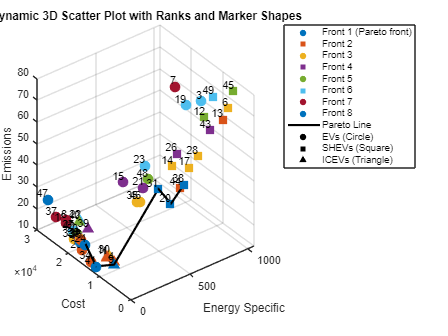

%plot_3D(pop, powertrains)

% % Get the current user's root directory (platform independent)
% user_root = userpath; % Gets the MATLAB default user folder
% 
% % Remove the trailing semicolon from userpath (MATLAB appends a semicolon)
% if user_root(end) == ';'
%     user_root(end) = [];
% end
% 
% % Define the relative folder path from the user's MATLAB directory
% save_directory = fullfile(user_root, 'NSGA-II', 'Results', save_folder);
% 
% save(fullfile(save_directory, 'powertrains.mat'), 'powertrains');
 elapsed_time = toc
% bdclose('all');


% % Display the layout and info of each stored powertrain
% emissions_data = zeros(1,stored_powertrains);
% cost_data = zeros(1,stored_powertrains);
% MAE_data = zeros(1,stored_powertrains);
% E_specific_data = zeros(1,stored_powertrains);
% icev = zeros(1,stored_powertrains);
% ev = zeros(1,stored_powertrains);
% shev = zeros(1,stored_powertrains);
% 
% for i = 1:stored_powertrains
%     disp(powertrains(i).results.layout);
%     if ismember('GEN', powertrains(i).results.layout)
%         shev(i) = 1;
%     elseif ismember('ICE', powertrains(i).results.layout)
%         icev(i) = 1;
%     elseif ismember('MOT', powertrains(i).results.layout)
%         ev(i) = 1;
%     end
%     emissions_data(i) = powertrains(i).results.emissions;
%     cost_data(i) = powertrains(i).results.cost;
%     MAE_data(i) = powertrains(i).results.MAE;
%     E_specific_data(i) = powertrains(i).results.E_specific;
% end

    {'BAT'}    {'MOT'}    {'TR'}    {'VEH'}

    {'BAT'}    {'MOT'}    {'TR'}    {'GEN'}    {'MOT'}    {'VEH'}

    {'FT'}    {'ICE'}    {'GEN'}    {'MOT'}    {'VEH'}

    {'BAT'}    {'MOT'}    {'VEH'}

    {'BAT'}    {'MOT'}    {'GEN'}    {'MOT'}    {'VEH'}

    {'FT'}    {'ICE'}    {'VEH'}

    {'FT'}    {'ICE'}    {'GEN'}    {'MOT'}    {'GB'}    {'TR'}    {'TR'}    {'GB'}    {'VEH'}

    {'BAT'}    {'MOT'}    {'TR'}    {'TR'}    {'GEN'}    {'MOT'}    {'GB'}    {'GB'}    {'VEH'}

    {'BAT'}    {'MOT'}    {'VEH'}

    {'BAT'}    {'MOT'}    {'GEN'}    {'MOT'}    {'VEH'}

    {'BAT'}    {'MOT'}    {'GB'}    {'VEH'}

    {'FT'}    {'ICE'}    {'TR'}    {'TR'}    {'VEH'}

    {'FT'}    {'ICE'}    {'VEH'}

    {'FT'}    {'ICE'}    {'GB'}    {'TR'}    {'TR'}    {'VEH'}

    {'FT'}    {'ICE'}    {'TR'}    {'GEN'}    {'MOT'}    {'TR'}    {'VEH'}

    {'BAT'}    {'MOT'}    {'GEN'}    {'MOT'}    {'VEH'}

    {'FT'}    {'ICE'}    {'GB'}    {'VEH'}

    {'BAT'}    {'MOT'}    {'GEN'}    {'MOT'}   

% T = table(MAE_data(:), emissions_data(:), cost_data(:), E_specific_data(:), 'VariableNames', {'MAE', 'Emissions (CO2 tons)', 'Cost (EUR)', 'E_specific'});
% disp(T);

      MAE       Emissions (CO2 tons)    Cost (EUR)    E_specific
    ________    ____________________    __________    __________

       2.428             13.5             12100           113.66
      6.5433             21.7             18200                0
      3.9873           69.485             10600           884.15
      4.8765             13.3             10300           129.03
      3.9121             19.5             16300                0
      4.8737           69.351              5700           979.64
    0.042045           70.762             16900           829.57
      3.2786            24.61             20750                0
      3.2811             12.7              9900           114.62
      3.4992             19.4             16200                0
    0.069972           14.775             11700           108.89
      5.8208      

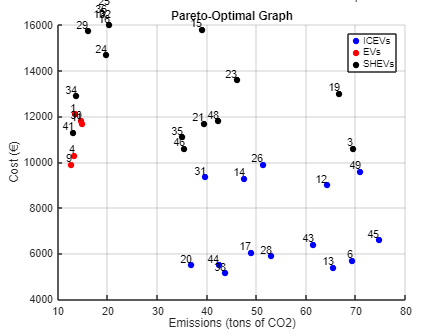

% 
% %% Pareto-Optimal Graph
% figure;
% hold on;
% scatter(emissions_data(icev == 1), cost_data(icev == 1), 'filled', 'MarkerFaceColor', 'b'); 
% scatter(emissions_data(ev == 1), cost_data(ev == 1), 'filled', 'MarkerFaceColor', 'r'); 
% scatter(emissions_data(shev == 1), cost_data(shev == 1), 'filled', 'MarkerFaceColor', 'k'); 
% 
% % Label the plotted points
% for i = 1:stored_powertrains
%     text(emissions_data(i), cost_data(i), num2str(i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
% end
% 
% % Create labels
% ax = gca;
% ax.YAxis.Exponent = 0;
% xlabel('Emissions (tons of CO2)');
% ylabel('Cost (€)');
% ylim([4000 16000])
% xlim([10 80])
% title('Pareto-Optimal Graph');
% legend('ICEVs', 'EVs', 'SHEVs', 'location', 'Northeast');
% grid on;
% hold off;

% 
% %% Other information
% elapsed_time_minutes = elapsed_time / 60;

Unrecognized function or variable 'elapsed_time'.

% fprintf('The elapsed time is %.2f minutes.\n', elapsed_time_minutes);
% fprintf('The number of created powertrains is %d.\n', created_powertrains);

figurine =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


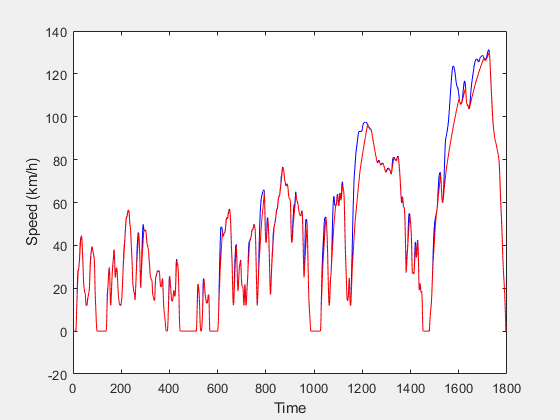

figurine =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


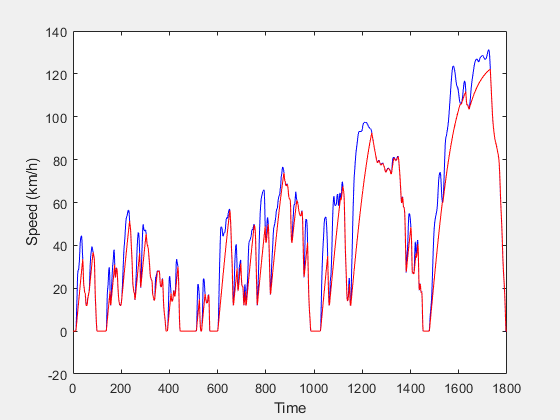

figurine =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


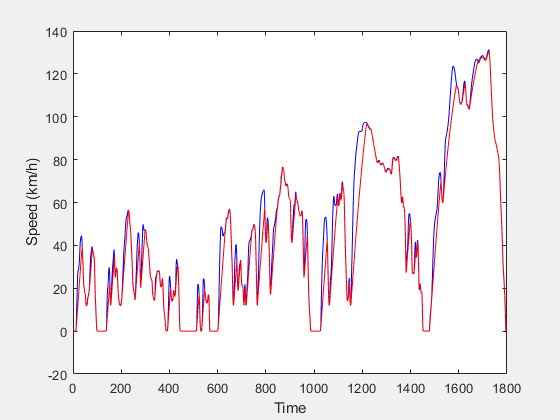

figurine =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


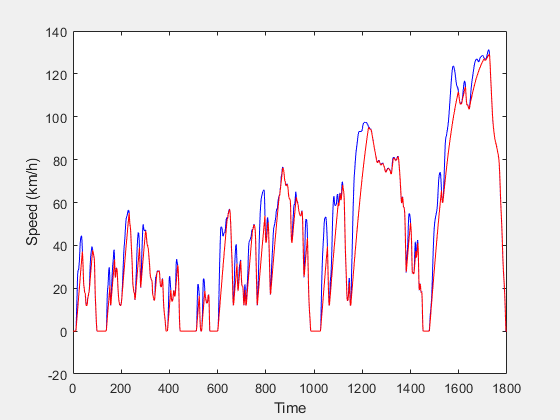

figurine =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


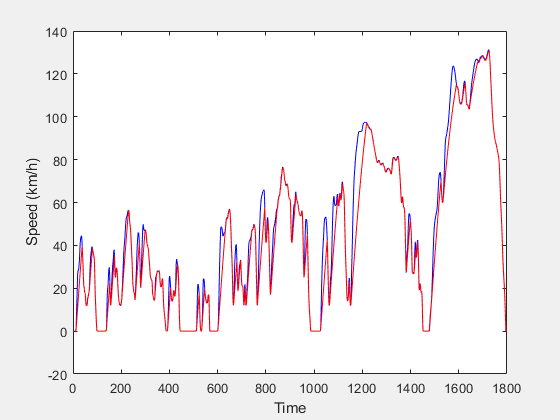

figurine =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


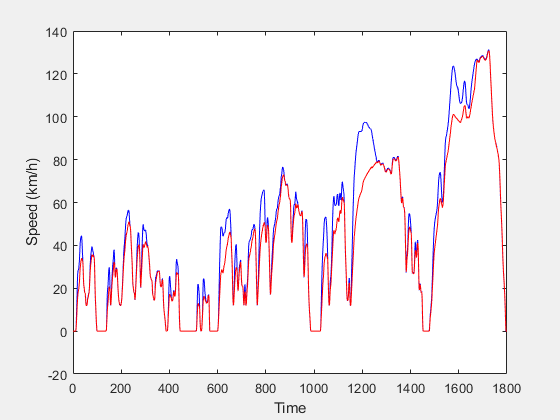

figurine =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


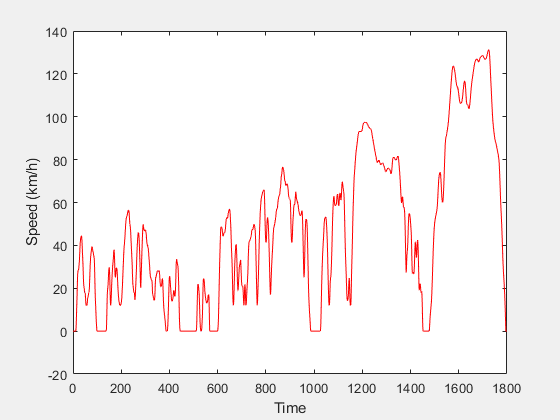

figurine =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


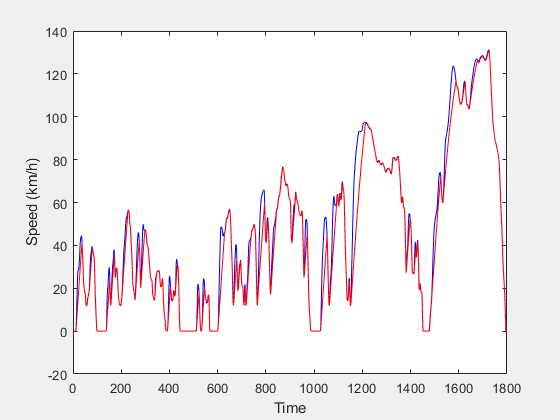

figurine =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


figurine =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


%for i = 1:10
%figurine = powertrains(i).results.fig
%figure(figurine)
%end 

% Convert struct array to a cell array for compatibility
powertrains_cell = arrayfun(@(x) struct(x), powertrains, 'UniformOutput', false);
assignin('base', 'powertrains_cell', powertrains_cell);